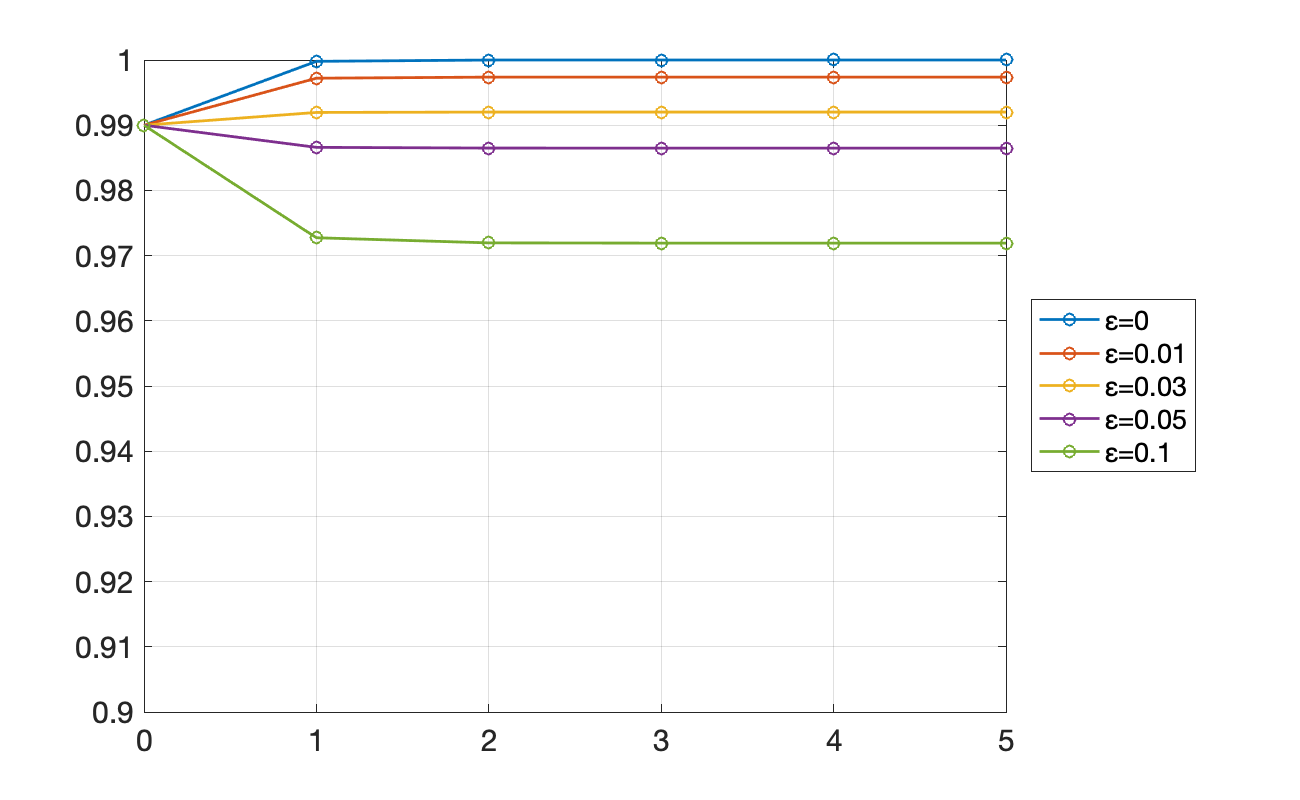

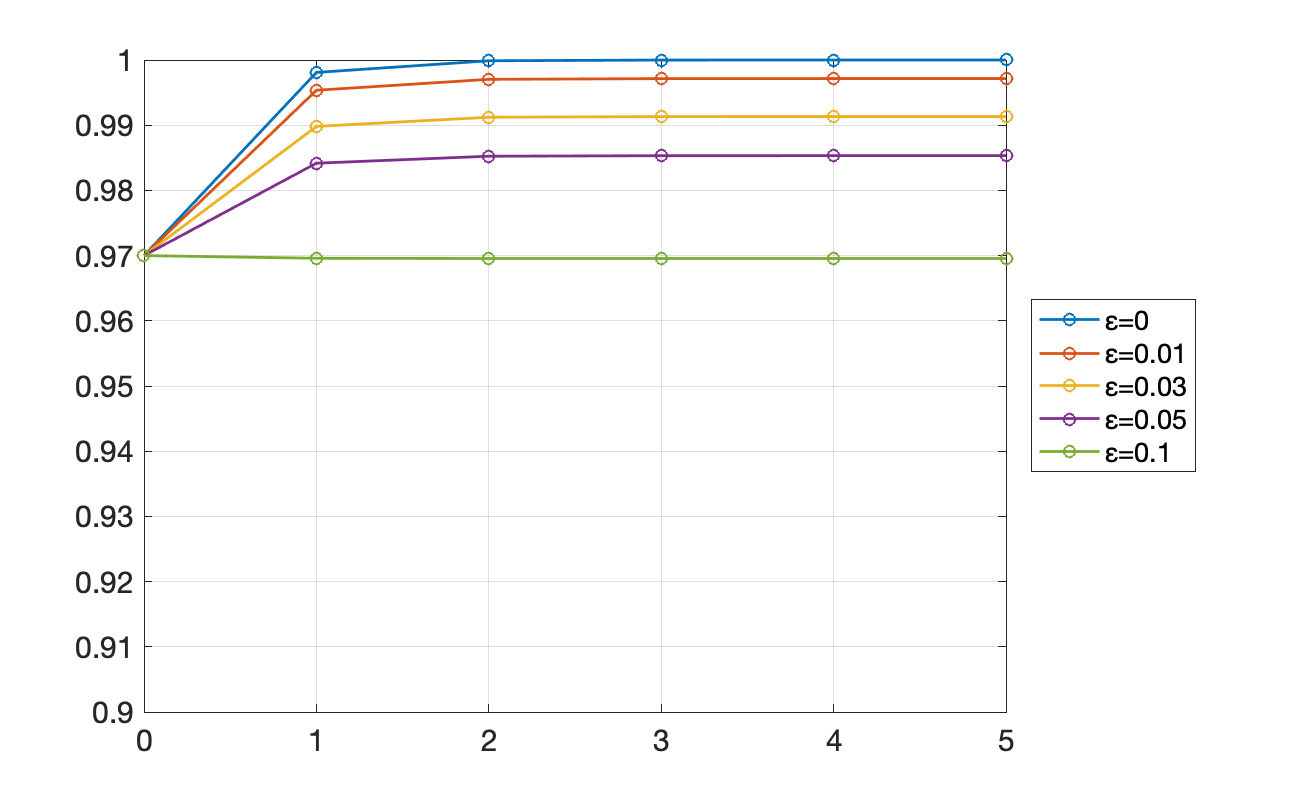

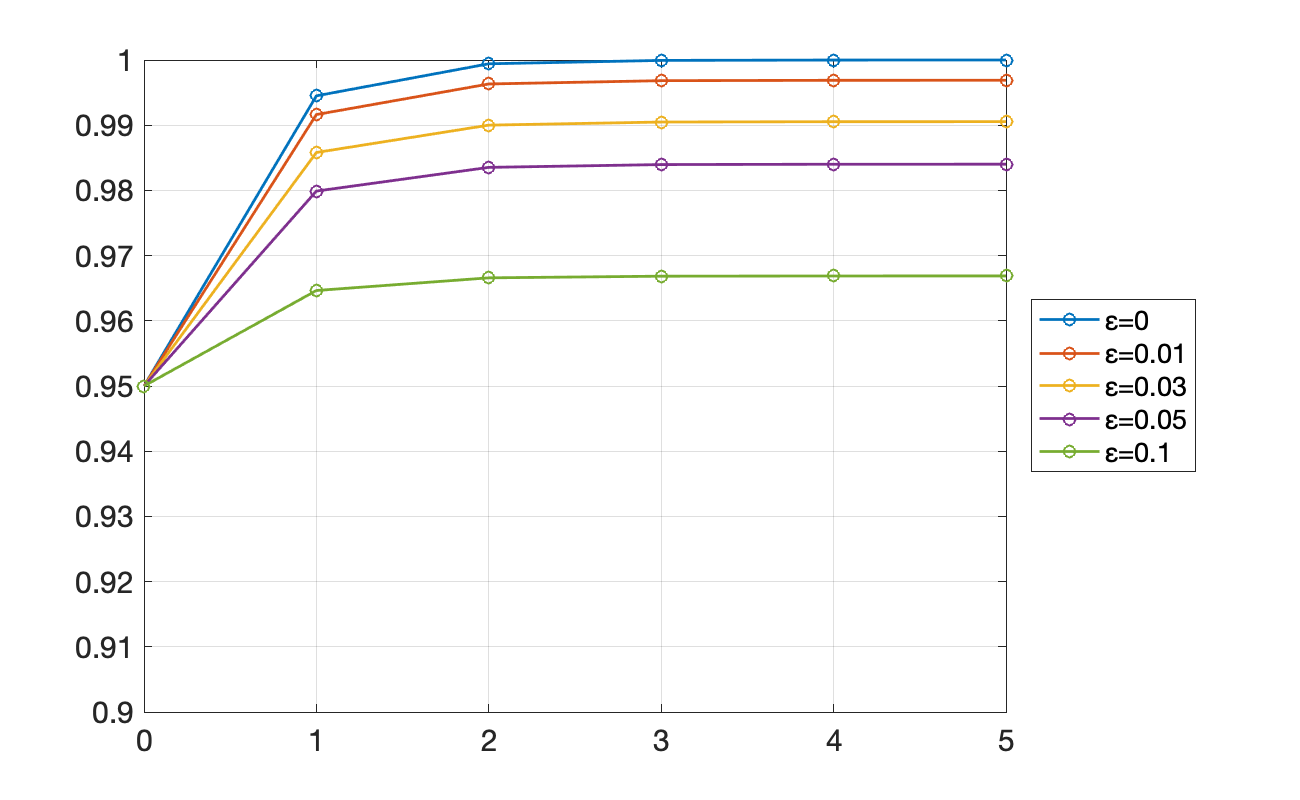

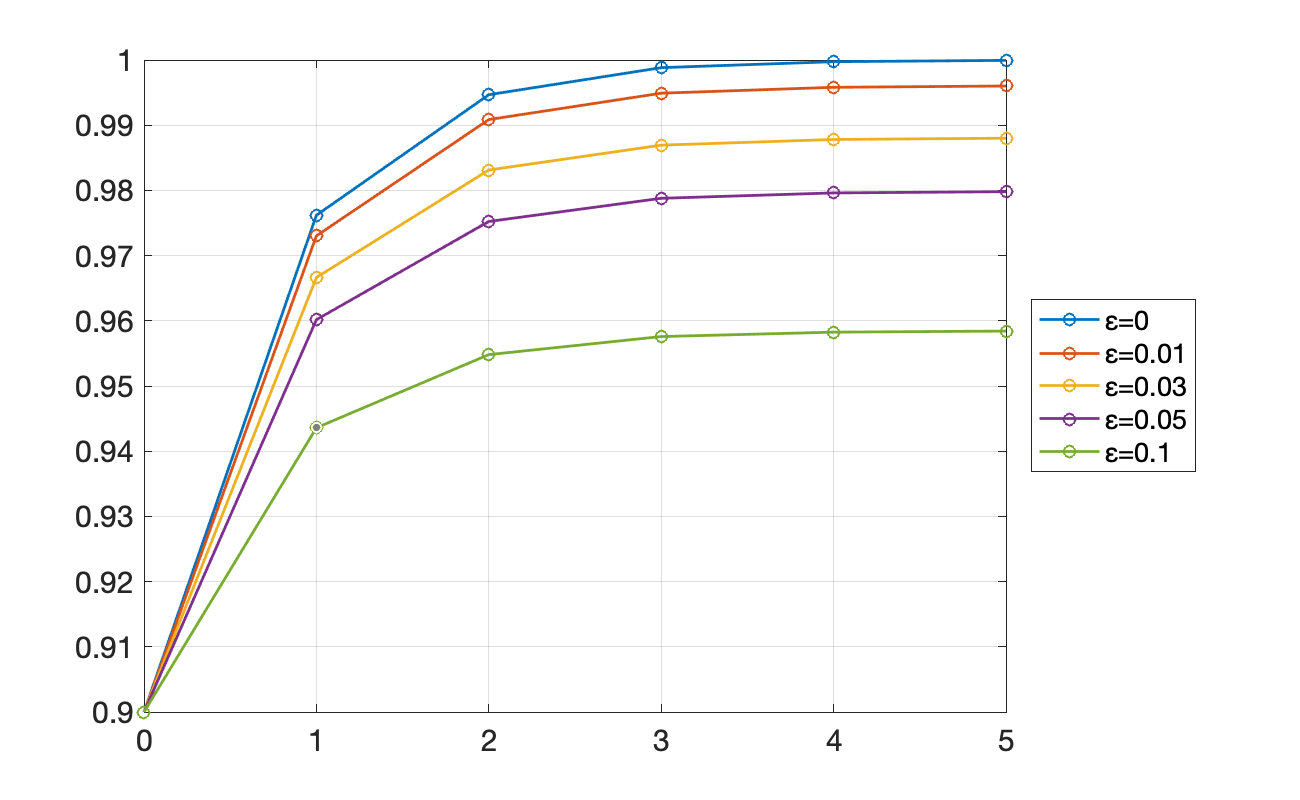

n_values = 0:5;
F0_values = zeros(size(n_values));

for p = [0.01 0.03 0.05 0.1]
    f0=1-p;
    q=p;
    figure('Position', [100, 100, 650, 400]);
    for eps = [0 0.01 0.03 0.05 0.1]
        for i = 1:length(n_values)
        n = n_values(i);
        [x0, x1] = calculate_preparations(f0, q, eps, n);
        [F0, F1] = calculate_fidelities(x0, x1);
        F0_values(i) = F0;
        end
    plot(n_values, F0_values, "-o", "DisplayName",['ε=',num2str(eps)],'LineWidth',1.4);
    hold on;
    end
    hold off;
    % Adjust tick font size
    set(gca, 'FontSize', 15); % Adjust FontSize as desired
    % title(['Graph of the fidelity after purification with 1-f=q=',num2str(p)]);
    % xlabel('n');
    % ylabel('f');
    grid on;
    ylim([0.9 1])
    legend('Location','eastoutside'); % Places the legend outside the plot on the right
end

function [x0, x1] = calculate_preparations(f0, q, r, n)
    f1 = 1 - f0;
    x0 = f0;
    x1 = f1;
    for k = 1:n
        trc=x0+x1;
        x0 = (1-r)*(x0 * ((1 - q) * f0 + q * f1)) + r*trc/4;
        x1 = (1-r)*(x1 * ((1 - q) * f1 + q * f0)) + r*trc/4;
    end    
end

function [m0, m1] = calculate_measurements(f0, q, r, n)
    f1 = 1 - f0;
    m0 = 1-q;
    m1 = q;
    for k = 1:n
        trc=m0+m1;
        m0 = (1-r)*(m0 * (f0 * (1-q) + f1 * q)) + r*trc/4;
        m1 = (1-r)*(m1 * (f0 * q + f1 * (1-q))) + r*trc/4;
    end    
end

function [X0, X1] = fractal_preparations(x0, x1, y0, y1, r, n)
    X0=x0;
    X1=x1;
    for k = 1:n
        trc=X0+X1;
        X0 = (1-r)*X0*(x0*y0 + x1*y1) + r*trc/4;
        X1 = (1-r)*X1*(x0*y1 + x1*y0) + r*trc/4;
    end    
end

function [Y0,Y1] = fractal_measurements(x0, x1, y0, y1, r, n)
    Y0=y0;
    Y1=y1;
    for k = 1:n
        trc=y0+y1;
        Y0 = (1-r)*Y0*(x0*y0 + x1*y1) + r*trc/4;
        Y1 = (1-r)*Y1*(x0*y1 + x1*y0) + r*trc/4;
    end    
end

function [f0, f1] = calculate_fidelities(x0, x1)
    f0 = x0/(x0+x1);
    f1 = x1/(x0+x1);
end

function F = converging_fidelity(f0, q, r)
    if r == 0
        F = 1;
    else
        D= 2*(1-r)*(1-2*q)*(2*f0-1)/r;
        F = 1/(1-D+sqrt(D^2+1));
    end
end